# FFUAV Senior Design - James Objective Funtion

## Housekeeping

clc; clear; close all;

## Load Data

load("Battery_chem.mat");
load("All_motor_Prop_combos.mat");
load("all_batteries.mat");

% INPUTS -------------------------------------------------------------
 % Propulsion System
        Num_p_systems = 8; % Number of propulsion Systems
        manufacture_offset = 1.075;
        coaxial_system = 0;
        
        % Battery Type and Sizing
        Bat_Capacity = 40 % amp - Hours

Bat_Capacity = 40

        number_of_cells = 12; 
        Battery_Type = "Li-Hv"; % determines battery chemistery
        if Battery_Type == "Li-Po"
                Battery_chemistery_trial = Battery_chemistry(2,:);
        end
        if Battery_Type == "Li-Hv"
                Battery_chemistery_trial = Battery_chemistry(3,:);
        end
        if Battery_Type == "Li-Ion"
                Battery_chemistery_trial = Battery_chemistry(4,:);
        end
        if Battery_Type == "SS Li-Ion"
                Battery_chemistery_trial = Battery_chemistry(5,:);
        end
        
        Bat_Usage = 0.80;    % max battery allowed to be used
        
        % Aircraft weight estimation - Grams
        airframe = 11500;
        Propulsion = 3600;
        Autopilot_electronics = 500;
        Payload = 25 * 453.592 % lbs --> grams

Payload = 1.1340e+04

        misc = 500;
        aircraft_weights = [airframe, Propulsion, Autopilot_electronics, Payload, misc];
        
        % Aircraft Experimental weights - Grams
        airframe = 8359;
        Propulsion = 5572;
        Autopilot_electronics = 0;
        Payload = 25 * 453.592 % lbs --> grams

Payload = 1.1340e+04

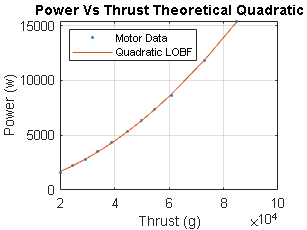

        misc = 0;
        aircraft_weights = [airframe, Propulsion, Autopilot_electronics, Payload, misc];
        
        % Range and Speed Variables
        Range_conversion_factor = 1.0;
        Target_range_miles = 10.00; % miles
        Estimated_cruise_speed_mph = 25;% mph
        Estimated_aircraft_drag_grams = 7500*25^2/35^2; % grams
        % Minumum Thrust to weight ratio
        TW = 2.0;
        
        if(coaxial_system)
            thrust_multiplier = 0.8;
        else
            Thrust_multiplier = 1;
        end
% OUTPUTS --------------------------------------------------------------

% Define looping variables
best = [1, 0];
old = [0, 0];
% Loop start
for i = 10

        % Battery Specifications
        low_battery_voltage = Battery_chemistery_trial{7};
        nom_battery_voltage = Battery_chemistery_trial{11};
        Battery_energy_density = Battery_chemistery_trial{3};
        Battery_weight_est = Bat_Capacity * nom_battery_voltage / Battery_energy_density;
        Battery_C_rating = Battery_chemistery_trial{2};
        
        % quadratic Power Vs Thrust
        Thrust_newtons = nonzeros(rmmissing(allMPCs(i).Thrust_N(:,2)));
        Thrust_grams = Thrust_newtons * 101.971621297793; % convert to grams
        Power_Watts = nonzeros(rmmissing((allMPCs(i).Power_W(:,2))));
        Total_thrust_newtons = Thrust_multiplier * Thrust_newtons * Num_p_systems;
        Total_thrust_grams = Total_thrust_newtons * 101.971621297793; %convert to grams
        Total_power_watts = Num_p_systems * Power_Watts * manufacture_offset;
        %plotting
        figure(1)
        quad_coefs = polyfit(Total_thrust_grams,Total_power_watts,2);
        power_fit = polyval(quad_coefs,Total_thrust_grams);
        plot(Total_thrust_grams,Total_power_watts,'.')
        hold on
        plot(Total_thrust_grams,power_fit)
        title("Power Vs Thrust Theoretical Quadratic")
        xlabel("Thrust (g)")
        ylabel("Power (w)")
        legend("Motor Data", "Quadratic LOBF",'Location','northwest')
        grid on
        
        %Aircraft Weight Estimates - grams
        Aircraft_empty_weight_w_payload_g = sum(aircraft_weights);
        Aircraft_all_up_weight_g = Aircraft_empty_weight_w_payload_g + Battery_weight_est;
        Aircraft_weight_w_drag_g = Aircraft_all_up_weight_g + Estimated_aircraft_drag_grams;
        
        % Power Consumption Estimates
        Hover_power_consumption_watts = quad_coefs(1)*Aircraft_all_up_weight_g^2 + quad_coefs(2)*Aircraft_all_up_weight_g + quad_coefs(3);
        Cruise_power_consumption_watts = quad_coefs(1)*Aircraft_weight_w_drag_g^2 + quad_coefs(2)*Aircraft_weight_w_drag_g + quad_coefs(3);
        Cruise_power_consumption_C = Cruise_power_consumption_watts / (nom_battery_voltage*Bat_Capacity);
        
        % FLight Time and Range Estimation
        Hover_flight_time_minutes = Bat_Capacity * nom_battery_voltage * Bat_Usage / Hover_power_consumption_watts * 60;
        Cruise_flight_time_minutes = Bat_Capacity * nom_battery_voltage * Bat_Usage / Cruise_power_consumption_watts * 60;
        Direct_line_range = Cruise_flight_time_minutes / 60 * Estimated_cruise_speed_mph;
        
        % Battery Capacity range Calculations
        Max_Thrust_grams = max(Total_thrust_grams);
        Battery_testing_voltage = mean(nonzeros(rmmissing(allMPCs(i).Voltage(2,:))));
        Max_thrust_dead_battery = (low_battery_voltage/Battery_testing_voltage)^1.5 * Max_Thrust_grams;
        
        % Thrust to weight ratio at dead battery
        Thrust_to_weight_ratio_dead_battery = Max_thrust_dead_battery / Aircraft_all_up_weight_g;
        
        Max_taekoff_weight_grams = Max_thrust_dead_battery/TW;
        Max_battery_weight_grams = Max_taekoff_weight_grams - Aircraft_empty_weight_w_payload_g;
        Max_battery_capacity_Ah = Max_battery_weight_grams * Battery_energy_density / nom_battery_voltage;
        
        if Thrust_to_weight_ratio_dead_battery >= TW
            % Thrust to weight constraint passed
            if Cruise_power_consumption_C < (0.66 * Battery_C_rating)
                % Cruise Power constraint passed
                if Direct_line_range > old(2)
                    % store best
                    best = [i, Direct_line_range, Aircraft_all_up_weight_g];
                    old = best;
                end
            end
        end
end

disp(best)

   1.0e+04 *

    0.0010    0.0009    3.3562

